% load dataset
load toy.dat

[N, I] = size(toy)

N = 10

I = 3

X = [ones(N, 1), toy(:, 1:2)] % apply ones on the column to account for biases in weights vector

X =     1.0000    2.0000    3.0000
    1.0000    3.0000    2.0000
    1.0000    3.0000    6.0000
    1.0000    5.5000    4.5000
    1.0000    5.0000    3.0000
    1.0000    7.0000    4.0000
    1.0000    5.0000    6.0000
    1.0000    8.0000    6.0000
    1.0000    9.5000    5.0000
    1.0000    9.0000    7.0000


targets = toy(:, 3) % targets is third column

targets =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1



alpha = 0.01

alpha = 0.0100

proposalWidth = 0.1

proposalWidth = 0.1000

[weightsStored_HMC, weightsIndep_HMC] = hamiltonianMCBayesSingleNeuron(X, targets, alpha);

Acceptance rate: 0.920909


weightsIndep_HMC

weightsIndep_HMC =   -11.0648    2.3715   -0.3891
  -10.6018    1.7257    0.0997
  -23.2830    2.3489    2.0153
  -19.5647    1.9873    1.6870
  -27.9641    4.4466    0.8908
  -20.7463    2.7534    1.2713
   -9.1228    1.9967    0.1880
  -19.0683    2.3920    1.2488
  -15.2337    2.5232    0.2961
  -15.9784    2.1962    0.8754


[weightsStored_Met, weightsIndep_Met] = metropolisMCBayesSingleNeuron(X, targets, alpha, proposalWidth);

Acceptance rate = 0.497536 


weightsIndep_Met

weightsIndep_Met =   -21.9739    4.0252    0.0462
  -20.7735    1.9187    1.9729
   -8.3583    2.1937   -1.0991
   -2.1451    0.9535   -1.0397
   -7.1927    0.8837    0.5700
  -17.3704    1.9385    1.8094
   -3.9458    0.2499    0.6343
   -7.4932    0.6100    1.0765
  -11.0343    0.9480    1.0692
  -21.3030    2.4724    1.5408


## Plotting Learned Y mean (predicted probabilities) from Metropolis


% Getting the test data
x1 = linspace(0, 10);
x2 = x1; 
[x1 x2] = meshgrid(x1, x2);

testX = [ones(10000, 1), x1(:), x2(:)];

% learned y part : calculate predicted probabilities of targets = 1
% testX = M x I
% weightsIndep = R x I, where R = number of independent samples. 

probTargetIsOne_Met = mean( sigmoid(weightsIndep_Met * testX') );

probTargetIsOne_Met

probTargetIsOne_Met =     0.0042    0.0039    0.0037    0.0035    0.0033    0.0031    0.0030    0.0028    0.0027    0.0027    0.0026    0.0026    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0033    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0047    0.0050    0.0053    0.0056    0.0059    0.0063    0.0067    0.0071    0.0075    0.0080    0.0085    0.0090    0.0096    0.0102    0.0108    0.0115    0.0123    0.0131    0.0140    0.0150


probTargetIsOne_HMC = mean( sigmoid(weightsIndep_HMC * testX') );

probTargetIsOne_HMC

probTargetIsOne_HMC =     0.1500    0.1518    0.1536    0.1555    0.1575    0.1595    0.1616    0.1638    0.1660    0.1683    0.1707    0.1731    0.1756    0.1782    0.1809    0.1836    0.1864    0.1893    0.1922    0.1953    0.1984    0.2016    0.2049    0.2082    0.2117    0.2152    0.2189    0.2226    0.2264    0.2304    0.2344    0.2386    0.2429    0.2473    0.2519    0.2565    0.2614    0.2664    0.2716    0.2770    0.2826    0.2885    0.2946    0.3010    0.3077    0.3148    0.3222    0.3302    0.3387    0.3477


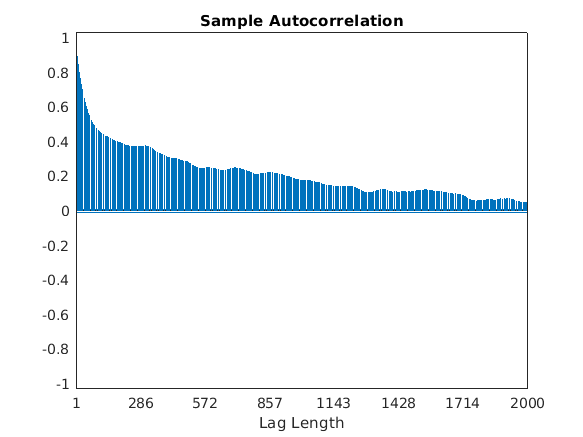


% Autocorrelations for Metropolis
figure(1); clf
lag = 2000;
acf(weightsStored_Met(:, 2), lag);

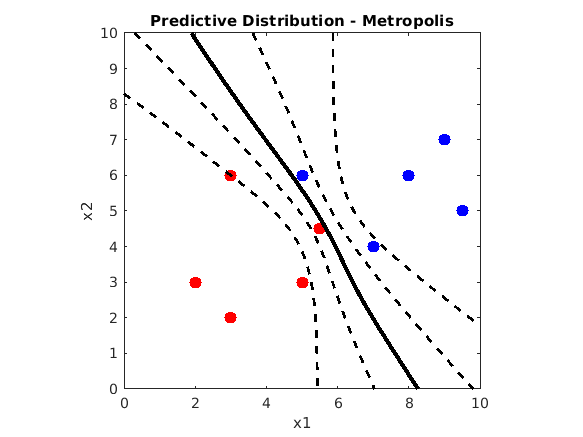



% Predictive distribution for Hamiltonian
figure(2); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]);
ylim([0 10]); 
axis square
title('Predictive Distribution - Metropolis'); xlabel('x1'); ylabel('x2')
hold on

% NOTE: x1, x2, probs/learnedYs are all 100 x 100 matrices
% need to reshape so probs are also 100 x 100
probs = reshape(probTargetIsOne_Met, 100, 100); 
contour(x1, x2, probs, 5, '--k', 'LineWidth', 2); 
hold on
contour(x1, x2, probs, 1,'k', 'LineWidth', 3); % [0.5 0.5] in place of 1

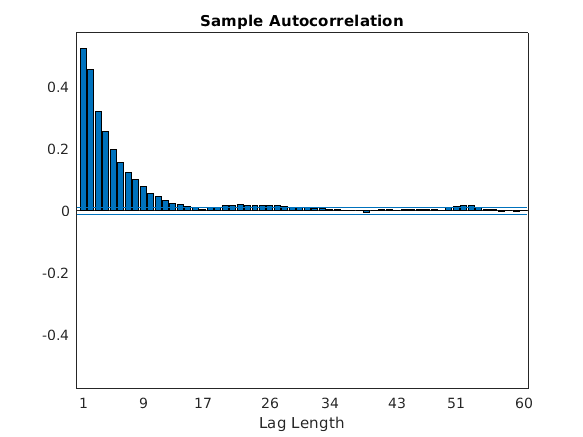


% Autocorrelations for Hamiltonian
figure(3); clf
lag = 60;
acf(weightsStored_HMC(:, 2), lag);

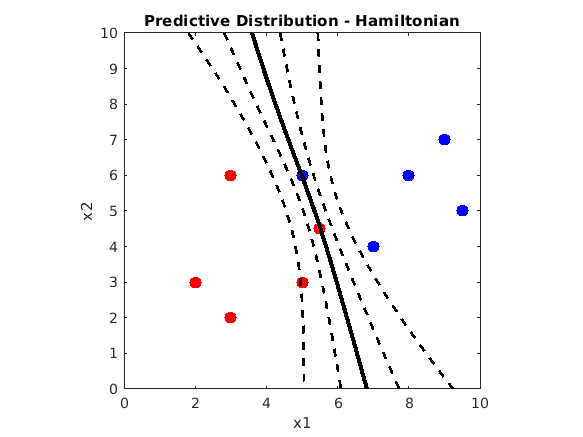



% Predictive distribution for Hamiltonian
figure(4); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]);
ylim([0 10]); 
axis square
title('Predictive Distribution - Hamiltonian'); xlabel('x1'); ylabel('x2')
hold on

% NOTE: x1, x2, probs/learnedYs are all 100 x 100 matrices
% need to reshape so probs are also 100 x 100
probs = reshape(probTargetIsOne_HMC, 100, 100); 
contour(x1, x2, probs, 5, '--k', 'LineWidth', 2); 
hold on
contour(x1, x2, probs, 1,'k', 'LineWidth', 3); % [0.5 0.5] in place of 1